## Read Task File

clear all
pwd

ans = '/mnt/D/Mastersharif/MasterProject/Surprise/Codes/brainsurprise2/brainsurprise/Surprise_codes'

T = readtable('../task_track_files/task_track_file_v3_PD_linux.csv','Format','%d%s%s%s%s%s%s%s%s%s%s%s%s')

T = 50×13 table
    Var1        local_file_path                 raw_data_file_name                         preprocessed_one                                  ICA_name                                        IC_Feature                                           R_squareds_BF                                            R_squareds_BF_permutation                                            R_squareds_three_state                                            R_squareds_three_state_permutation                                            R_squareds_KL                                            R_squareds_KL_permutation                        Group_file_type
    ____    _______________________    ____________________________________   

% Path = {'D:\Mastersharif\MasterProject\data\parkinsons-oddball'};
% linux version
Path = {'/mnt/D/Mastersharif/MasterProject/data/parkinsons-oddball'};
% Path_to_save_feature = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\IC_collected_trials';
% linux version
Path_to_save_feature = '/mnt/D/Mastersharif/MasterProject/data/parkinsons-oddball/EEG_feature/IC_collected_trials';
file_name = T{:,6};
newA = cellfun(@(x) strsplit(x, '.'), file_name, 'UniformOutput', false);
file_name = cellfun(@(x) x{1}, newA, 'UniformOutput', false);
% % High_pass = 38;
% % 
% % dir_name = ['EEGlab_pre_process_filtered_highpass_', num2str(High_pass)];
% m_1 =0.0001;
% m_2 =100;
% m_1 = 0.0001
% m_2 = 0.002
% m_1 = 0.01;
% m_2 = 2;
% for 2,11,18,16
% m_1 = 0.0001;
% m_2 = 2;
% T{:,7} = cellfun(@(x) [x(1:end-4),'_range_w_', num2str(m_1), '_', num2str(m_2),'_stored_b_final.mat'], T{:,7}, 'UniformOutput', false);
% T{:,12} = cellfun(@(x) [x(1:end-4),'_range_w_', num2str(m_1), '_', num2str(m_2),'.mat'], T{:,12}, 'UniformOutput', false);
dir_name = 'EEGlab_pre_process_'

dir_name = 'EEGlab_pre_process_'

## Check uncomplete tasks

% files_preprocessed = fullfile(Path_to_save_feature,dir_name,file_name,T{:,7});
files_preprocessed = fullfile(Path_to_save_feature,dir_name,file_name,T{:,7});

% files_preprocessed = fullfile(Path,T{:,2},T{:,5});
% flags = zeros(size(files_preprocessed));
% for i = 1:size(files_preprocessed, 2)
%     flags(i) = exist(files_preprocessed{i}, "file");
% end
flag=isfile(files_preprocessed);
task_not_completed = find(flag==0)';
temp = size(task_not_completed);
first_run = 1;
if temp(2) == 0
   load('run_features_PD_BF.mat')
   a = [a;[0.0001,50,100,0.0001,200,1000,0.1,3]];
   save('run_features_PD_BF.mat','a')
   first_run = 0 
   
end
% Path = 'D:\\Mastersharif\\MasterProject\\data\\parkinsons-oddball';

% Path_to_save_digit = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\digit_sequences';
Path_to_save_digit = '/mnt/D/Mastersharif/MasterProject/data/parkinsons-oddball/EEG_feature/digit_sequences';
file_name1 = T{:,3};

newA = cellfun(@(x) strsplit(x, '.'), file_name1, 'UniformOutput', false);
file_name1 = cellfun(@(x) x{1}, newA, 'UniformOutput', false);
Path_to_save_digit = fullfile(Path_to_save_digit,file_name1);
Path_to_save_digit_save = fullfile(Path_to_save_digit,'digit_sequences.mat');

### Check creation of digit sequences


flag=isfile(Path_to_save_digit_save);
task_not_completed = find(flag==0);
% temp = size(task_not_completed);

## Create DigitSequence

a=T{:,2};
b=T{:,3};
% linux version
flag = zeros(1,50)

flag =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Path = '/mnt/D/Mastersharif/MasterProject/data/parkinsons-oddball';
main_stimuli_name = {'S200','S201','S202'};
for i= 1:size(task_not_completed,2)
    k = task_not_completed(i)
    load_path = fullfile(Path, a{k}); %sprintf('%s/%s',Path,a{i});
    EEG = pop_loadset(b{k},load_path);   
    temp = load(Path_to_save_digit_save{k})
  
    
    temp = temp.Variable_name'
    
    a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
    b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
    c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
    first_stimulus = min([a1,b1,c1]);
    r={EEG(1).event(first_stimulus:end).type};
    
     newA = cellfun(@(x) x(4), r, 'UniformOutput', false);
     
     temp_2 = zeros(1,size(newA,2))
     for i=1:size(newA,2)
         temp_2(i) = str2double(newA{i});
     end
     
     flag(k) = (sum(temp_2+1 == temp)) == size(temp,2)
    
    
%     start_index = first_stimulus-1;
%     % 121 calculate
%     num_trials = size(EEG.event,2)-start_index;
%     digits_sequence = zeros(num_trials,1); 
%     index_s200 = find(strcmp({EEG(1).event(first_stimulus:end).type},main_stimuli_name{1})==1);
%     digits_sequence(index_s200) = 1;
%     index_s201 = find(strcmp({EEG(1).event(first_stimulus:end).type},main_stimuli_name{2})==1);
%     digits_sequence(index_s201) = 2;
%     index_s202 = find(strcmp({EEG(1).event(first_stimulus:end).type},main_stimuli_name{3})==1);
%     digits_sequence(index_s202) = 3;
%     wrapper_save(Path_to_save_digit_save{k},digits_sequence)
end

## Feature Generation

filtered preprocessed data to reach the frequency in the modir shanechi article.

Highpass_low = 1; % in Hz
Highpass_High = 38; % in Hz
% Notch_low = 59.9; % in Hz
% Notch_High = 60.1;% in Hz
% Notch_order = 16500;

Path = 'D:\\Mastersharif\\MasterProject\\data\\parkinsons-oddball';
% Path = '/home/kiani/DS/ds003490-download';
channellocationfile = fullfile({Path},T{1,2}{1},'sub-001_ses-01_task-Rest_electrodes.tsv');
channellocationfile = channellocationfile{1}
delete(gcp('nocreate'))

a=T{:,2};
b=T{:,4};
c=T{:,5};
parfor k=1:size(task_not_completed, 2)
    i = task_not_completed(k);
    load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
    EEG = pop_loadset(b{i},load_path);
    EEG = pop_eegfiltnew(EEG, 'locutoff',Highpass_low,'hicutoff',Highpass_High);
    EEG = pop_saveset( EEG, 'filename',c{i},'filepath',load_path);
    
end

## Feature Generation (Block one) with downsample

a=T{:,2};
b=T{:,4};
c=T{:,5};
d=T{:,6};

Path = 'D:\\Mastersharif\\MasterProject\\data\\parkinsons-oddball';
Path_to_save_feature = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\IC_collected_trials'

Path_to_save_feature = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\IC_collected_trials'

result_file_dir = fullfile(Path_to_save_feature,dir_name,file_name);
downsample_factor = 2;

parfor k=1:size(task_not_completed, 2)
    i = task_not_completed(k);
    load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
    
    if ~isfile(fullfile(load_path,c{i}))
        EEG = pop_loadset(b{i},load_path);
        EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','off','maxsteps',250,'stop',0.0001);
    
%     EEG_ica_path = fullfile(Path,a{i})
        pop_saveset(EEG,'filename',c{i},'filepath',load_path)
    else
        EEG = pop_loadset(c{i},load_path);
    end    
    
    num_component = size(EEG(1).icaweights,1);
    IC = (EEG.icaweights(1:num_component,:)*EEG.icasphere)*EEG(1).data(EEG.icachansind,:);
    main_stimuli_name = {'S200','S201','S202'};
    a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
    b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
    c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
    first_stimulus = min([a1,b1,c1]);
    start_index = first_stimulus-1;
    % 121 calculate
    num_trials = size(EEG.event,2)-start_index;
    time_index = zeros(1,num_trials);
    index_s200 = find(strcmp({EEG(1).event(first_stimulus:end).type},main_stimuli_name{1})==1) + start_index;
    index_s201 = find(strcmp({EEG(1).event(first_stimulus:end).type},main_stimuli_name{2})==1) + start_index;
    index_s202 = find(strcmp({EEG(1).event(first_stimulus:end).type},main_stimuli_name{3})==1) + start_index;
    off_set = 450/2;
    %     EEG = pop_saveset( EEG, 'filename',c{i},'filepath',load_path);
    time_index(index_s200-start_index) = [EEG(1).event(index_s200).latency] + off_set;
    time_index(index_s201-start_index) = [EEG(1).event(index_s201).latency] + off_set;
    time_index(index_s202-start_index) = [EEG(1).event(index_s202).latency];
    
    period_samples = -100:downsample_factor:245; % this period for ERP may has intersection with other stimuli ERP.
    
    num_samples_ERP = size(period_samples,2);
    
    time_index = time_index((time_index + period_samples(end))<size(EEG(1).data,2)); % filter stimuli which there is no appropriate ERP duration for them in EEG signal
    
    new_number_of_trials = size(time_index,2);
    temp = repmat(time_index,num_samples_ERP,1);
    matrix_time_index = temp + period_samples';
    
    
    Stimuli = IC(1:num_component,matrix_time_index);
    
    temp_1 = reshape(Stimuli,num_component,num_samples_ERP,new_number_of_trials);
    
    temp_2 = permute(temp_1,[3,2,1]);
    
    Output = reshape(temp_2,new_number_of_trials,num_samples_ERP*num_component);
    Final_Feature_Output =  Output;
    
    
    
%     dir_path = fullfile(Path_to_save_feature,dir_name,file_name(1:end-4));
    if ~isdir(result_file_dir{i})
        mkdir(result_file_dir{i})
    end    
    wrapper_save(fullfile(result_file_dir{i},d{i}),Final_Feature_Output);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
pop_loadset(): loading file D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-016\ses-02\eeg\pre_sub-016_ses-02_task-Rest_eeg.set ...
pop_loadset(): loading file D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-017\ses-02\eeg\pre_sub-017_ses-02_task-Rest_eeg.set ...
pop_loadset(): loading file D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-021\ses-01\eeg\pre_sub-021_ses-01_task-Rest_eeg.set ...
pop_loadset(): loading file D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-024\ses-02\eeg\pre_sub-024_ses-02_task-Rest_eeg.set ...
Reading float file 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\sub-016\ses-02\eeg\pre_sub-016_ses-02_task-Rest_eeg.fdt'...

Reading float file 'D:\Mastersharif\MasterProject\data\parkinsons-o

R_cv = zeros(1,50);
files_name_R_squareds = fullfile(Path_to_save_feature,dir_name,file_name,T{:,7});
for i=1:50
    if isfile(files_name_R_squareds{i}) && strcmp(T{i,13}{1},'PD_OFF')
        R_squared = load(files_name_R_squareds{i});
        R_squared = R_squared.Variable_name;
        
%         R_squared_permutation = load(files_name_R_squareds_permutation{i});
%         R_squared_permutation = R_squared_permutation.Variable_name;
%         
%         R_total(1,i) = R_squared{1};
%         R_total(2,i) = R_squared_permutation(1);

        R_cv(1,i) = R_squared{2};
%       R_cv(2,i) = R_squared_permutation(2);
    end

end 


R_cv = R_cv(R_cv~=0)

R_cv =     0.1027    0.0932    0.0714    0.0623    0.1738    0.0513    0.1017    0.0230    0.0819    0.1499    0.0636    0.1721    0.0604    0.0443    0.0681    0.0352    0.0906    0.0309    0.1405    0.1088    0.1061    0.1557    0.2268    0.0913    0.0356


mean(R_cv)

ans = 0.0936

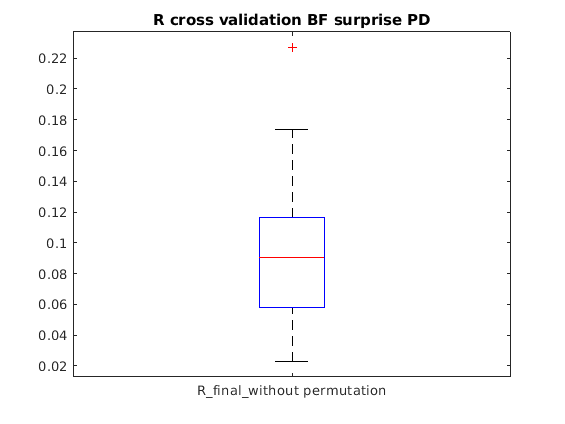

boxplot(R_cv','Labels',{'R_final_without permutation'})
title('R cross validation BF surprise PD')

## R-squared_calculation on all CTL for BF surprise

a=T{:,2}; 
b=T{:,3};
c=T{:,6};
d=T{:,7};



dir_name = 'EEGlab_pre_process_'

dir_name = 'EEGlab_pre_process_'


result_file_feature_dir = fullfile(Path_to_save_feature,dir_name,file_name);
% digit_sequences_file_dir = fullfile(Path_to_save_feature,dir_name,file_name);
% main_stimuli_name = {'S200','S201','S202'};
% task_not_completed = selected_index_bad_lambda_v1
% load('rerun_index.mat')
% task_not_completed = [2,11,16,18];
% task_not_completed = setdiff(task_not_completed,[13]);
% parfor(k=1:size(task_not_completed, 2),6)  
for k=1:size(task_not_completed,2)
     i = task_not_completed(k);
%     load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
% %     EEG = pop_loadset(b{i},load_path);
% %     
% %     a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
% %     b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
% %     c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
% %     first_stimulus = min([a1,b1,c1]);
% %     
% %     
% %     str_sequences = {EEG.event(first_stimulus:end).type};
% %     num_stimulus = size(str_sequences,2);
% %     digits_sequence = zeros(num_stimulus,1); 
% %     index = find(strcmp(str_sequences,main_stimuli_name{1})==1);
% %     digits_sequence(index) = 1;
% %     index = find(strcmp(str_sequences,main_stimuli_name{2})==1);
% %     digits_sequence(index) = 2;
% %     index = find(strcmp(str_sequences,main_stimuli_name{3})==1);
% %     digits_sequence(index) = 3;
%     
%     digits_sequence = load(fullfile(Path_to_save_digit{i},'digit_sequences.mat'))
    digits_sequence = load(Path_to_save_digit_save{i})
    digits_sequence = digits_sequence.Variable_name
    permutation = 1:size(digits_sequence,1)-1;
    Final_Feature_Output = load(fullfile(result_file_feature_dir{i},c{i}))
    Final_Feature_Output = Final_Feature_Output.Variable_name;
    [B_final,B0,R_max,lasso_min_mse,m_optiaml,lambda_min_mse] = lasso_regression(Final_Feature_Output,digits_sequence(1:end-1),0.0001,50,100,0.0001,200,1000,0.1,3,permutation);
     Y=BF_sur(digits_sequence,0.1,m_optiaml,3);
    Y=Y(permutation);
    fits = B0 + Final_Feature_Output*B_final;
    mse = mean((Y-fits).^2);
    R = 1 - mse/var(Y)
    Final_set = {R,R_max,m_optiaml,lambda_min_mse,B_final,B0};
    if first_run==1
        wrapper_save(fullfile(result_file_feature_dir{i},d{i}),Final_set);
    elseif R_cv(i)>R_max
         wrapper_save(fullfile(result_file_feature_dir{i},d{i}),Final_set);   
    end
end   

digits_sequence = struct with fields:
    Variable_name: [63×1 double]


digits_sequence =      2
     2
     3
     2
     2
     3
     2
     2
     1
     2


Final_Feature_Output = struct with fields:
    Variable_name: [62×10899 double]


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


R = 0.1642

## R-squared_calculation on all CTL with permutation with BF_surprise

c=T{:,6};
d=T{:,8};

dir_name = 'EEGlab_pre_process_'
result_file_feature_dir = fullfile(Path_to_save_feature,dir_name,file_name);
number_permutation = 5;


dir_name = 'EEGlab_pre_process_'

% task_not_completed = setdiff(task_not_completed,[2,3,5,6,8,9,11,13,16,20])

parfor k=1:size(task_not_completed, 2)
    i = task_not_completed(k);
%     load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
%     EEG = pop_loadset(b{i},load_path);
    
%     a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
%     b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
%     c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
%     first_stimulus = min([a1,b1,c1]);
%     
%     
%     str_sequences = {EEG.event(first_stimulus:end).type};
%     num_stimulus = size(str_sequences,2);
%     digits_sequence = zeros(num_stimulus,1); 
%     index = find(strcmp(str_sequences,main_stimuli_name{1})==1);
%     digits_sequence(index) = 1;
%     index = find(strcmp(str_sequences,main_stimuli_name{2})==1);
%     digits_sequence(index) = 2;
%     index = find(strcmp(str_sequences,main_stimuli_name{3})==1);
%     digits_sequence(index) = 3;
    
%     wrapper_save(fullfile(result_file_dir{i},'digit_sequences.mat'),digits_sequence);
    digits_sequence = load(fullfile(Path_to_save_digit{i},'digit_sequences.mat'));
    digits_sequence = digits_sequence.Variable_name; 
    Final_Feature_Output = load(fullfile(result_file_feature_dir{i},c{i}));
    Final_Feature_Output = Final_Feature_Output.Variable_name;
    R_max_mean = 0;
    R_mean = 0;
    m_optimal_mean = 0;
    m_optimal = 0;
    lambda_min_mse_mean = 0;
    for j=1:number_permutation
        permutation = randperm(size(digits_sequence,1));
        [B_final,B0,R_max,lasso_min_mse,m_optiaml,lambda_min_mse] = lasso_regression(Final_Feature_Output,digits_sequence,0.0001,0.02,20,0.01,100,200,0.1,3,permutation);
        Y=BF_sur(digits_sequence,0.1,m_optiaml,3);
        Y=Y(permutation);
        fits = B0 + Final_Feature_Output*B_final;
        mse = mean((Y-fits).^2);
        R = 1 - mse/var(Y);
        R_mean = ((j-1)*R_mean + R)/j;
        R_max_mean =  ((j-1)*R_max_mean + R_max)/j;
        m_optimal_mean = ((j-1)*m_optimal_mean + m_optiaml)/j;
        lambda_min_mse_mean = ((j-1)*lambda_min_mse_mean + lambda_min_mse)/j;
        m_optimal_mean = ((j-1)*m_optimal_mean + m_optimal)/j;
    end 
    
    Final_set = [R_mean,R_max_mean,m_optimal_mean,lambda_min_mse_mean];
    
    wrapper_save(fullfile(result_file_feature_dir{i},d{i}),Final_set)
    
    
end  

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


## R-squared_calculation on all CTL with three state

c=T{:,6};
d=T{:,9};
i=1

i = 1

% dir_name = ['EEGlab_pre_process_filtered_highpass_', num2str(High_pass)];
result_file_dir = fullfile(Path_to_save_feature,dir_name,file_name);

digit_sequences_file_dir = fullfile(Path_to_save_feature,dir_name,file_name);
main_stimuli_name = {'S200','S201','S202'};
task_not_completed = [1:25];
m_1 = 5

m_1 = 5

m_2 = 20

m_2 = 20

parfor k=1:size(task_not_completed, 2)
    i = task_not_completed(k);
%     load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
%     EEG = pop_loadset(b{i},load_path);
    
%     a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
%     b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
%     c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
%     first_stimulus = min([a1,b1,c1]);
%     
%     
%     str_sequences = {EEG.event(first_stimulus:end).type};
%     num_stimulus = size(str_sequences,2);
%     digits_sequence = zeros(num_stimulus,1); 
%     index = find(strcmp(str_sequences,main_stimuli_name{1})==1);
%     digits_sequence(index) = 1;
%     index = find(strcmp(str_sequences,main_stimuli_name{2})==1);
%     digits_sequence(index) = 2;
%     index = find(strcmp(str_sequences,main_stimuli_name{3})==1);
%     digits_sequence(index) = 3;
    
%     wrapper_save(fullfile(result_file_dir{i},'digit_sequences.mat'),digits_sequence);
    digits_sequence = load(fullfile(Path_to_save_digit{i},'digit_sequences.mat'));
    digits_sequence = digits_sequence.Variable_name; 
    Final_Feature_Output = load(fullfile(result_file_dir{i},c{i}));
    Final_Feature_Output = Final_Feature_Output.Variable_name;

 
    permutation = 1:size(digits_sequence,1);
    [B_final,B0,R_max,lasso_min_mse,m_optiaml] = lasso_regression(Final_Feature_Output,digits_sequence,m_1,m_2,50,0.01,100,2000,0.1,3,permutation);
    Y=three_state_sur(digits_sequence,m_optiaml);
    Y=Y(permutation);
    fits = B0 + Final_Feature_Output*B_final;
    mse = mean((Y-fits).^2);
    R = 1 - mse/var(Y);
    Final_set = {R,R_max,m_optiaml,B_final};    
    wrapper_save(fullfile(result_file_dir{i},d{i}),Final_set)
    
end 

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


## R-squared_calculation on all CTL  with three state with permutation

c=T{:,6};
d=T{:,10};
% dir_name = ['EEGlab_pre_process_filtered_highpass_', num2str(High_pass)];
result_file_dir = fullfile(Path_to_save_feature,dir_name,file_name);
digit_sequences_file_dir = fullfile(Path_to_save_feature,dir_name,file_name);
main_stimuli_name = {'S200','S201','S202'};
number_permutation = 5;

for k=1:size(task_not_completed, 2)
    i = task_not_completed(k);
%     load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
%     EEG = pop_loadset(b{i},load_path);
    
%     a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
%     b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
%     c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
%     first_stimulus = min([a1,b1,c1]);
%     
%     
%     str_sequences = {EEG.event(first_stimulus:end).type};
%     num_stimulus = size(str_sequences,2);
%     digits_sequence = zeros(num_stimulus,1); 
%     index = find(strcmp(str_sequences,main_stimuli_name{1})==1);
%     digits_sequence(index) = 1;
%     index = find(strcmp(str_sequences,main_stimuli_name{2})==1);
%     digits_sequence(index) = 2;
%     index = find(strcmp(str_sequences,main_stimuli_name{3})==1);
%     digits_sequence(index) = 3;
%     wrapper_save(fullfile(result_file_dir{i},'digit_sequences.mat'),digits_sequence);
    digits_sequence = load(fullfile(Path_to_save_digit{i},'digit_sequences.mat'))
    digits_sequence = digits_sequence.Variable_name 
    Final_Feature_Output = load(fullfile(result_file_dir{i},c{i}))
    Final_Feature_Output = Final_Feature_Output.Variable_name;
    R_max_mean = 0;
    R_mean = 0;
    m_optimal_mean = 0;
    m_optimal = 0;
    lambda_min_mse_mean = 0;
    lambda_min_mse = 0;
    for j=1:number_permutation
        permutation = randperm(size(digits_sequence,1));
        [B_final,B0,R_max,lasso_min_mse,m_optimal,lambda_min_mse] = lasso_regression(Final_Feature_Output,digits_sequence,5,20,50,0.01,100,2000,0.1,3,permutation);
        Y=three_state_sur(digits_sequence,m_optimal);
        Y=Y(permutation);
        fits = B0 + Final_Feature_Output*B_final;
        mse = mean((Y-fits).^2);
        R = 1 - mse/var(Y)
        R_mean = ((j-1)*R_mean + R)/j;
        R_max_mean =  ((j-1)*R_max_mean + R_max)/j;
        m_optimal_mean = ((j-1)*m_optimal_mean + m_optimal)/j;
        lambda_min_mse_mean = ((j-1)*lambda_min_mse_mean + lambda_min_mse)/j;
    end 
    Final_set = [R_mean,R_max_mean,m_optimal_mean,lambda_min_mse_mean];
    wrapper_save(fullfile(result_file_dir{i},d{i}),Final_set);
end

## R squared calculation for KL without permutation

a=T{:,2};
b=T{:,3};
c=T{:,6};
d=T{:,11};



dir_name = 'EEGlab_pre_process_'

dir_name = 'EEGlab_pre_process_'


result_file_feature_dir = fullfile(Path_to_save_feature,dir_name,file_name);
% digit_sequences_file_dir = fullfile(Path_to_save_feature,dir_name,file_name);
% main_stimuli_name = {'S200','S201','S202'};
% load('up_bad_KL.mat')
m_1 = 1

m_1 = 1

m_2 = 100

m_2 = 100

parfor k=1:size(task_not_completed, 2)  
     i = task_not_completed(k);
%     load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
% %     EEG = pop_loadset(b{i},load_path);
% %     
% %     a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
% %     b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
% %     c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
% %     first_stimulus = min([a1,b1,c1]);
% %     
% %     
% %     str_sequences = {EEG.event(first_stimulus:end).type};
% %     num_stimulus = size(str_sequences,2);
% %     digits_sequence = zeros(num_stimulus,1); 
% %     index = find(strcmp(str_sequences,main_stimuli_name{1})==1);
% %     digits_sequence(index) = 1;
% %     index = find(strcmp(str_sequences,main_stimuli_name{2})==1);
% %     digits_sequence(index) = 2;
% %     index = find(strcmp(str_sequences,main_stimuli_name{3})==1);
% %     digits_sequence(index) = 3;
%     
    digits_sequence = load(fullfile(Path_to_save_digit{i},'digit_sequences.mat'));
    digits_sequence = digits_sequence.Variable_name;
    permutation = 1:size(digits_sequence,1);
    Final_Feature_Output = load(fullfile(result_file_feature_dir{i},c{i}))
    Final_Feature_Output = Final_Feature_Output.Variable_name;
    [B_final,B0,R_max,lasso_min_mse,m_optimal,lambda_min_mse] = lasso_regression(Final_Feature_Output,digits_sequence,m_1,m_2,100,0.01,200,2000,0.1,3,permutation);
    Y=KL(digits_sequence,m_optimal);
    Y=Y(permutation);
    fits = B0 + Final_Feature_Output*B_final;
    mse = mean((Y-fits).^2);
    R = 1 - mse/var(Y);
    Final_set = {R,R_max,m_optimal,lambda_min_mse,B_final};
    wrapper_save(fullfile(result_file_feature_dir{i},d{i}),Final_set)
end    
 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\IC_collected_trials\EEGlab_pre_process_filtered_highpass_38\ICA_filtered_pre_sub-003_ses-01_task-Rest_eeg'

ans = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\IC_collected_trials\EEGlab_pre_process_filtered_highpass_38\ICA_filtered_pre_sub-003_ses-01_task-Rest_eeg'

R squared calculation for KL with permutation

c=T{:,6};
d=T{:,12};

dir_name = 'EEGlab_pre_process_'

dir_name = 'EEGlab_pre_process_'

result_file_feature_dir = fullfile(Path_to_save_feature,dir_name,file_name);
number_permutation = 5;
% load('up_bad_KL.mat')
% task_not_completed = setdiff(task_not_completed,selected_index_bad_lambda_v1_up)

parfor k=1:size(task_not_completed, 2)
    i = task_not_completed(k);
%     load_path = fullfile(Path, a{i}); %sprintf('%s/%s',Path,a{i});
%     EEG = pop_loadset(b{i},load_path);
    
%     a1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{1})==1,1);
%     b1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{2})==1,1);
%     c1 = find(strcmp({EEG(1).event(1:end).type},main_stimuli_name{3})==1,1);
%     first_stimulus = min([a1,b1,c1]);
%     
%     
%     str_sequences = {EEG.event(first_stimulus:end).type};
%     num_stimulus = size(str_sequences,2);
%     digits_sequence = zeros(num_stimulus,1); 
%     index = find(strcmp(str_sequences,main_stimuli_name{1})==1);
%     digits_sequence(index) = 1;
%     index = find(strcmp(str_sequences,main_stimuli_name{2})==1);
%     digits_sequence(index) = 2;
%     index = find(strcmp(str_sequences,main_stimuli_name{3})==1);
%     digits_sequence(index) = 3;
    
%     wrapper_save(fullfile(result_file_dir{i},'digit_sequences.mat'),digits_sequence);
    digits_sequence = load(fullfile(Path_to_save_digit{i},'digit_sequences.mat'));
    digits_sequence = digits_sequence.Variable_name; 
    Final_Feature_Output = load(fullfile(result_file_feature_dir{i},c{i}));
    Final_Feature_Output = Final_Feature_Output.Variable_name;
    R_max_mean = 0;
    R_mean = 0;
    m_optimal_mean = 0;
    m_optimal = 0;
    lambda_min_mse_mean = 0;
    for j=1:number_permutation
        permutation = randperm(size(digits_sequence,1));
        [B_final,B0,R_max,lasso_min_mse,m_optiaml,lambda_min_mse] = lasso_regression(Final_Feature_Output,digits_sequence,m_1,m_2,50,0.01,200,2000,0.1,3,permutation);
        Y=BF_sur(digits_sequence,0.1,m_optiaml,3);
        Y=Y(permutation);
        fits = B0 + Final_Feature_Output*B_final;
        mse = mean((Y-fits).^2);
        R = 1 - mse/var(Y);
        R_mean = ((j-1)*R_mean + R)/j;
        R_max_mean =  ((j-1)*R_max_mean + R_max)/j;
        m_optimal_mean = ((j-1)*m_optimal_mean + m_optiaml)/j;
        lambda_min_mse_mean = ((j-1)*lambda_min_mse_mean + lambda_min_mse)/j;
        m_optimal_mean = ((j-1)*m_optimal_mean + m_optiaml)/j;
    end 
    
    Final_set = [R_mean,R_max_mean,m_optimal_mean,lambda_min_mse_mean];
    
    wrapper_save(fullfile(result_file_feature_dir{i},d{i}),Final_set)
    
    
end 

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


## Plot R_squared Box Plot

R_cv_max = zeros(1,25);
R_cv_base = zeros(1,25);
files_name_R_squareds = fullfile(Path_to_save_feature,dir_name,file_name,T{:,7});
for i=1:25
        R_squared = load(files_name_R_squareds{i});
        R_squared = R_squared.Variable_name;
        
%         R_squared_permutation = load(files_name_R_squareds_permutation{i});
%         R_squared_permutation = R_squared_permutation.Variable_name;
%         
%         R_total(1,i) = R_squared{1};
%         R_total(2,i) = R_squared_permutation(1);

        R_cv_base(1,i) = R_squared(2);
%         R_cv(2,i) = R_squared_permutation(2);

end  


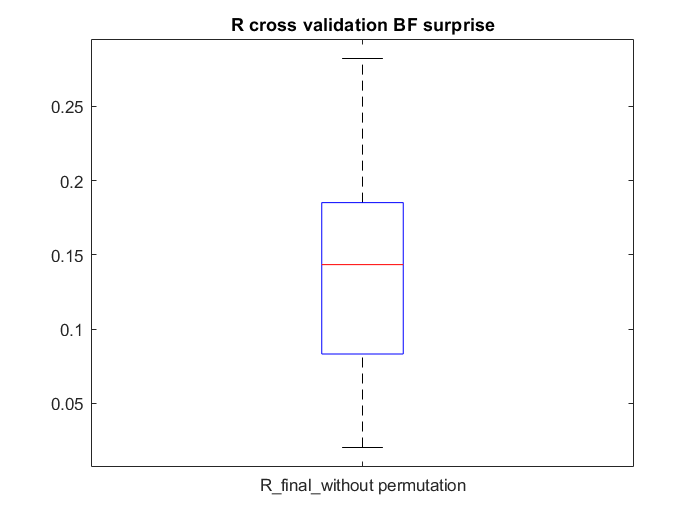

boxplot(R_cv_base','Labels',{'R_final_without permutation'})
title('R cross validation BF surprise')

load R_squared signal

% selected version:
% m_1 =0.0001;
% m_2 =100;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%selected version with combined name file with perivious version
% m_1 = 0.0001
% m_2 = 0.002
% selected_version
% m_1 = 0.01;
% m_2 = 2;
% for 2,11,18,16
% selected_Version
m_1 = 0.0001;
m_2 = 100;
temp = cellfun(@(x) [x(1:end-4),'_range_w_', num2str(m_1), '_', num2str(m_2),'_stored_b_final.mat'], T{:,7}, 'UniformOutput', false);
m_1 = 0.0001;
m_2 = 0.002;
temp = cellfun(@(x) [x(1:end-4),'_range_w_', num2str(m_1), '_', num2str(m_2),'_stored_b_final.mat'], temp, 'UniformOutput', false);
% files_preprocessed = fullfile(Path_to_save_feature,dir_name,file_name,temp);

% files_preprocessed = fullfile(Path,T{:,2},T{:,5});
% flags = zeros(size(files_preprocessed));
% for i = 1:size(files_preprocessed, 2)
%     flags(i) = exist(files_preprocessed{i}, "file");
% end


files_name_R_squareds = fullfile(Path_to_save_feature,dir_name,file_name,temp);
flag=isfile(files_name_R_squareds);
task_not_completed = find(flag==0)';
% files_name_R_squareds_permutation = fullfile(Path_to_save_feature,dir_name,file_name,T{:,8});
% R_total = zeros(2,25);

for i=1:25
    if isfile(files_name_R_squareds{i})
        R_squared = load(files_name_R_squareds{i});
        R_squared = R_squared.Variable_name;
        
%         R_squared_permutation = load(files_name_R_squareds_permutation{i});
%         R_squared_permutation = R_squared_permutation.Variable_name;
%         
%         R_total(1,i) = R_squared{1};
%         R_total(2,i) = R_squared_permutation(1);
          if R_squared{2}> R_cv_max(i)
             R_cv_max(i) =  R_squared{2};
          end  
%         R_cv(1,i) = R_squared{2};
%         R_cv(2,i) = R_squared_permutation(2);
    end
end 



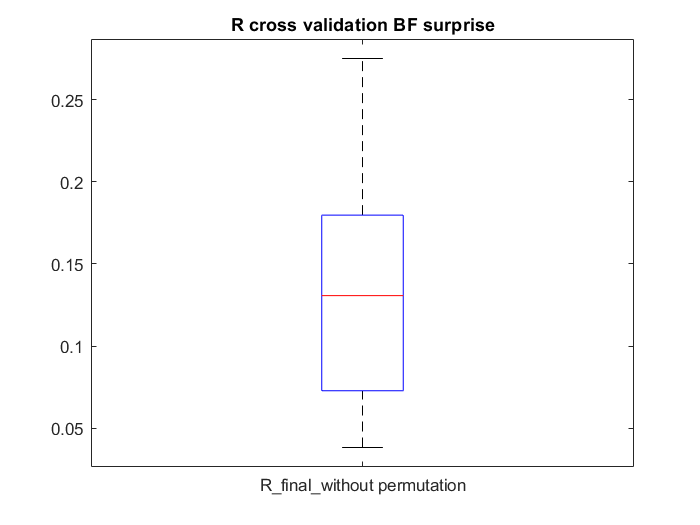

figure;
boxplot(R_cv_max','Labels',{'R_final_without permutation'})
title('R cross validation BF surprise')

Select bad subject for Buf without permutation

files_name_R_squareds = fullfile(Path_to_save_feature,dir_name,file_name,T{:,7});
% files_name_R_squareds_permutation = fullfile(Path_to_save_feature,dir_name,file_name,T{:,8});
R_total = zeros(2,25);
R_cv = zeros(2,25);
selected_index_bad_lambda = [];
selected_index_bad_m_up = [];
selected_index_bad_m_low = [];
for i=1:25
    R_squared = load(files_name_R_squareds{i});
    R_squared = R_squared.Variable_name;
    if R_squared{4}==100
        selected_index_bad_lambda = [selected_index_bad_lambda, i];
    end
    if (R_squared{3}-0.0001)<1*0.1
        selected_index_bad_m_up = [selected_index_bad_m_up, i];
    end
    if (100-R_squared{3})<1*0.1
        selected_index_bad_m_low = [selected_index_bad_m_low, i];
    end
end

Error using load
Unable to read file 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\IC_collected_trials\EEGlab_pre_process_\IC_Feature_sub-030_ses-01_task-Rest_eeg\R_squareds_BF_v3_sub-030_ses-01_task-Rest_eeg_range_w_0.01_2_stored_b_final.mat'. No such file or directory.

files_name_R_squareds = fullfile(Path_to_save_feature,dir_name,file_name,T{:,9});
% files_name_R_squareds_permutation = fullfile(Path_to_save_feature,dir_name,file_name,T{:,8});
R_total = zeros(2,25);
R_cv = zeros(2,25);
selected_index_bad_lambda_v1 = [];
% selected_index_bad_m_up_v1 = [];
% selected_index_bad_m_low = [];
for i=1:25
    R_squared = load(files_name_R_squareds{i});
    R_squared = R_squared.Variable_name;
    if R_squared(4)==100
        selected_index_bad_lambda_v1 = [selected_index_bad_lambda_v1, i];
    end
%     if (R_squared(3)-0.01)<1*0.1
%         selected_index_bad_m_up = [selected_index_bad_m_up, i];
%     end
%     if (2-R_squared(3))<1*0.1
%         selected_index_bad_m_low = [selected_index_bad_m_low, i];
%     end
end


Plot box plot for BF_sur

f=figure
boxplot(R_total','Labels',{'R_final_without permutation','R_final_with_permutation'})
title('R final BF surprise')
saveas(f,'R_final_squared_BF_v1.png')

f =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


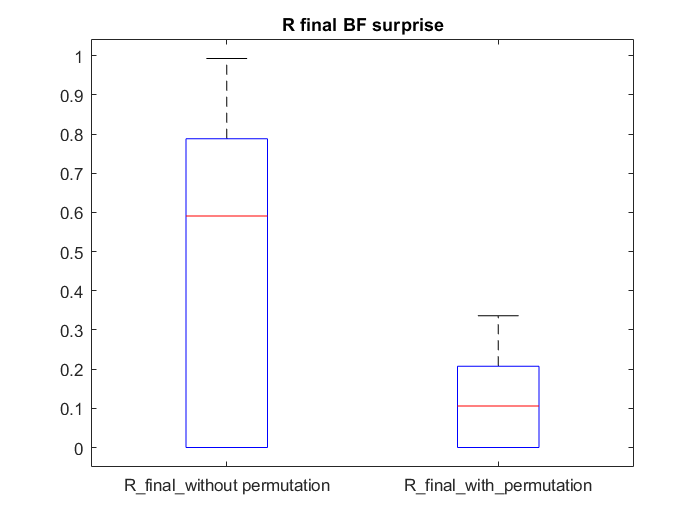

f=figure
boxplot(R_cv','Labels',{'R_final_without permutation','R_final_with_permutation'})
title('R cross validation BF surprise')

saveas(f,'R_cross_validation_BF_v1.png')

f =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


Three state

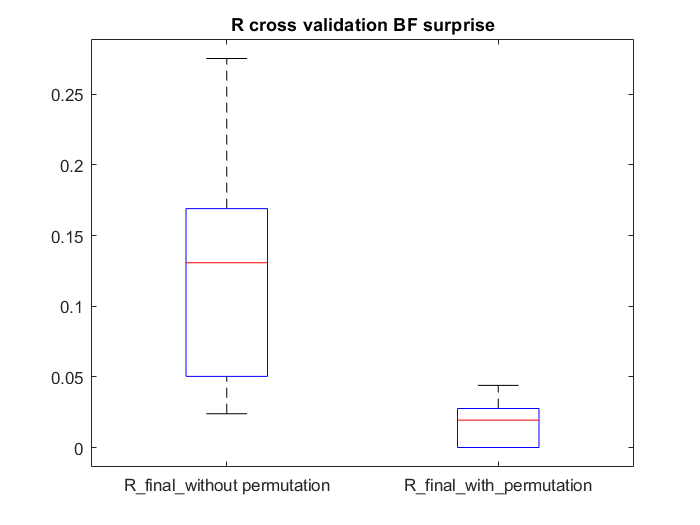

files_name_R_squareds = fullfile(Path_to_save_feature,dir_name,file_name,T{:,9});
files_name_R_squareds_permutation = fullfile(Path_to_save_feature,dir_name,file_name,T{:,10});
R_total = zeros(2,25);

R_cv_three = zeros(2,25);
for i=1:25
    R_squared = load(files_name_R_squareds{i});
    R_squared = R_squared.Variable_name;
    
    R_squared_permutation = load(files_name_R_squareds_permutation{i});
    R_squared_permutation = R_squared_permutation.Variable_name;
    
    R_total(1,i) = R_squared{1};
    R_total(2,i) = R_squared_permutation(1);
    
    R_cv_three(1,i) = R_squared{2};
    R_cv_three(2,i) = R_squared_permutation(2);
end    


f=figure
boxplot(R_total','Labels',{'R_final_without permutation','R_final_with_permutation'})
title('R final three state')

Error using load
Unable to read file 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\IC_collected_trials\EEGlab_pre_process_\IC_Feature_sub-003_ses-01_task-Rest_eeg\R_squareds_three_state_permutation_v3_sub-003_ses-01_task-Rest_eeg.mat'. No such file or directory.

saveas(f,'R_final_squared_three_State.png')
f=figure
boxplot(R_cv','Labels',{'R_final_without permutation','R_final_with_permutation'})
title('R cross validation')
saveas(f,'R_cross_validation_three_State.png')
 

KL 

files_name_R_squareds = fullfile(Path_to_save_feature,dir_name,file_name,T{:,11});
files_name_R_squareds_permutation = fullfile(Path_to_save_feature,dir_name,file_name,T{:,12});
R_total = zeros(2,25);
R_cv = zeros(2,25);
for i=1:25
    R_squared = load(files_name_R_squareds{i});
    R_squared = R_squared.Variable_name;
    
    R_squared_permutation = load(files_name_R_squareds_permutation{i});
    R_squared_permutation = R_squared_permutation.Variable_name;
    
    R_total(1,i) = R_squared{1};
    R_total(2,i) = R_squared_permutation(1);
    
    R_cv(1,i) = R_squared{2};
    R_cv(2,i) = R_squared_permutation(2);
end


selected_index_bad_lambda_v1_up_1 = []


selected_index_bad_lambda_v1_up_1 =

     []



selected_index_bad_lambda_v1_down = [];
files_name_R_squareds = fullfile(Path_to_save_feature,dir_name,file_name,T{:,11});
selected_index_bad_lambda_v1_up_1 = [];
for i=1:25
    R_squared = load(files_name_R_squareds{i});
    R_squared = R_squared.Variable_name;
    if R_squared{4}==200
        selected_index_bad_lambda_v1_up_1 = [selected_index_bad_lambda_v1_up_1, i];
    end
    if R_squared{4}==0.01
        selected_index_bad_lambda_v1_down = [selected_index_bad_lambda_v1, i];
    end
%     if (R_squared(3)-0.01)<1*0.1
%         selected_index_bad_m_up = [selected_index_bad_m_up, i];
%     end
%     if (2-R_squared(3))<1*0.1
%         selected_index_bad_m_low = [selected_index_bad_m_low, i];
%     end
end

save('up_bad_KL.mat','selected_index_bad_lambda_v1_up')
load('up_bad_KL.mat')

f=figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


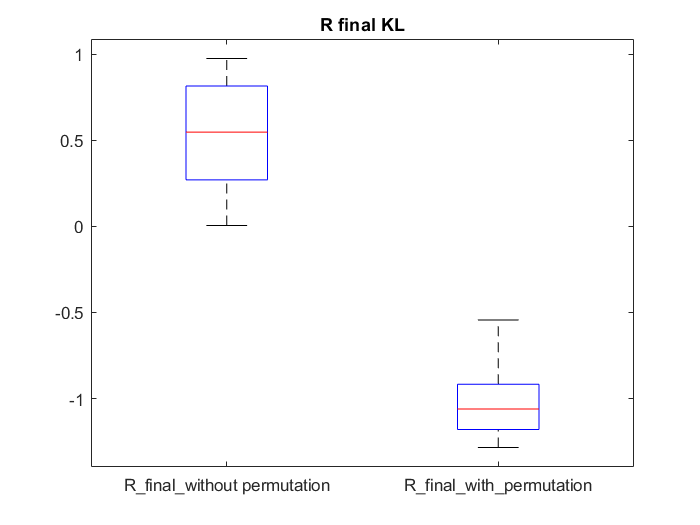

boxplot(R_total','Labels',{'R_final_without permutation','R_final_with_permutation'})
title('R final KL')
saveas(f,'R_final_squared_BF_v1.png')

f=figure

f =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


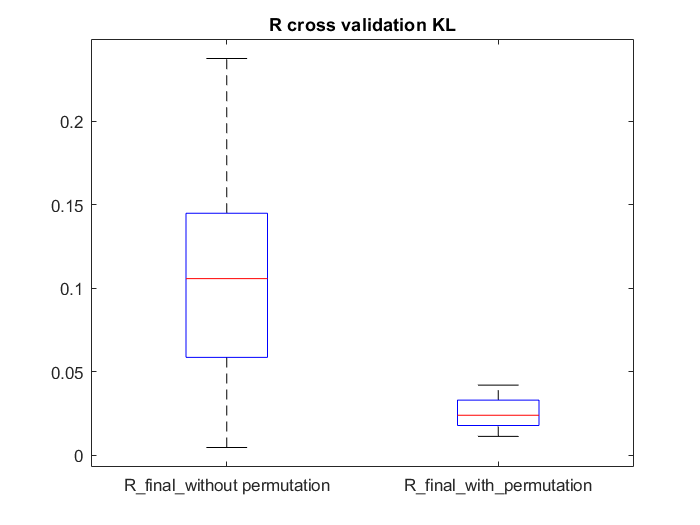

boxplot(R_cv','Labels',{'R_final_without permutation','R_final_with_permutation'})
title('R cross validation KL')
saveas(f,'R_cross_validation_BF_v1.png')

## Feature Generation (Block one)

load a data related to a subject

Generation of features using the first version of preprocessing

% clear all; % temporary command
% % Path = 'D:\\Mastersharif\\MasterProject\\data\\parkinsons-oddball';
% file_name = 'Faster_sub-003_ses-01_task-Rest_eeg.set';
% % Load_Path = fullfile(Path,'Checking_preprocess\Temperory\sub38\Faster_results_3')
% Path = 'C:\Users\mohammad\Documents\Check_Faster_2\sub-003\ses-01\eeg'
% EEG = pop_loadset(file_name,Path);
% EEG(1).data = double(EEG(1).data);
% ICs = (EEG(1).icaweights*EEG(1).icasphere)*EEG(1).data;
% 
% main_stimuli_name = {'S200','S201','S202'};
% num_component = size(EEG(1).icaweights,1);
% num_trials = size(EEG.event,2)-121;
% time_index = zeros(1,size(EEG(1).event,2)-121);
% index_s200 = find(strcmp({EEG(1).event(122:end).type},main_stimuli_name{1})==1) + 121;
% index_s201 = find(strcmp({EEG(1).event(122:end).type},main_stimuli_name{2})==1) + 121;
% index_s202 = find(strcmp({EEG(1).event(122:end).type},main_stimuli_name{3})==1) + 121;
% off_set = 450/2
% 
% time_index(index_s200-121) = [EEG(1).event(index_s200).latency] + off_set;
% time_index(index_s201-121) = [EEG(1).event(index_s201).latency] + off_set;
% time_index(index_s202-121) = [EEG(1).event(index_s202).latency];
% 
% 
% period_samples = -100:300;% this period for ERP may has intersection with other stimuli ERP.
% 
% num_samples_ERP = size(period_samples,2);
% 
% time_index = time_index((time_index + period_samples(end))<size(EEG(1).data,2)); % filter stimuli which there is no appropriate ERP duration for them in EEG signal
% 
% temp = repmat(time_index,num_samples_ERP,1);
% matrix_time_index = temp + period_samples';
% 
% 
% Stimuli = ICs(1:num_component,matrix_time_index);
% 
% temp_1 = reshape(Stimuli,num_component,num_samples_ERP,num_trials);
% 
% temp_2 = permute(temp_1,[3,2,1]);
% 
% Output = reshape(temp_2,num_trials,num_samples_ERP*num_component);
% Final_Feature_Output =  Output;

### Feature Generation (Block one) with downsample

% clear all; % temporary command
% T = readtable('../task_track_file.csv','Format','%d%s%s%s%s%s%s%s')
% Path = 'D:\\Mastersharif\\MasterProject\\data\\parkinsons-oddball';
file_name = 'Faster_sub-003_ses-01_task-Rest_eeg.set';
Pre_EEG_Data_name = 'Faster_sub-003_ses-01_task-Rest_eeg';
Path_to_save_feature = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\Surprise_EEG_features';
% Load_Path = fullfile(Path,'Checking_preprocess\Temperory\sub38\Faster_results_3')
% Path_to_datasets = '/mnt/D/Mastersharif/MasterProject/data/parkinsons-oddball';
Path = 'C:\Users\mohammad\Documents\Check_Faster_2\sub-005\ses-01\eeg';
Path_to_datasets = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball';
% Path = '/mnt/C/Users/mohammad/Documents/Check_Faster_3/sub-003/ses-01/eeg'
i = find(strcmp(T.Group_file_type,'CTL'));
Path = fullfile(Path_to_datasets,T.local_file_path{i(4)})
file_name = T.preprocessed_one{i(4)};
EEG = pop_loadset(file_name,Path);
% trun 57 to symbol
EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','off','maxsteps',250,'stop',0.0001);

num_component = size(EEG(1).icaweights,1);

IC = (EEG.icaweights(1:num_component,:)*EEG.icasphere)*EEG(1).data(EEG.icachansind,:);

main_stimuli_name = {'S200','S201','S202'};
% 121 calculate
num_trials = size(EEG.event,2)-121;
time_index = zeros(1,size(EEG(1).event,2)-121);
index_s200 = find(strcmp({EEG(1).event(122:end).type},main_stimuli_name{1})==1) + 121;
index_s201 = find(strcmp({EEG(1).event(122:end).type},main_stimuli_name{2})==1) + 121;
index_s202 = find(strcmp({EEG(1).event(122:end).type},main_stimuli_name{3})==1) + 121;
off_set = 450/2

time_index(index_s200-121) = [EEG(1).event(index_s200).latency] + off_set;
time_index(index_s201-121) = [EEG(1).event(index_s201).latency] + off_set;
time_index(index_s202-121) = [EEG(1).event(index_s202).latency];


period_samples = -100:2:245;% this period for ERP may has intersection with other stimuli ERP.

num_samples_ERP = size(period_samples,2);

time_index = time_index((time_index + period_samples(end))<size(EEG(1).data,2)); % filter stimuli which there is no appropriate ERP duration for them in EEG signal

temp = repmat(time_index,num_samples_ERP,1);
matrix_time_index = temp + period_samples';


Stimuli = IC(1:num_component,matrix_time_index);

temp_1 = reshape(Stimuli,num_component,num_samples_ERP,num_trials);

temp_2 = permute(temp_1,[3,2,1]);

Output = reshape(temp_2,num_trials,num_samples_ERP*num_component);
Final_Feature_Output =  Output;

Path_to_save_feature = 'D:\Mastersharif\MasterProject\data\parkinsons-oddball\EEG_feature\IC_collected_trials'
dir_path = fullfile(Path_to_save_feature,'EEGlab_pre_process',file_name(1:end-4))
mkdir(dir_path)
save(fullfile(dir_path,'IC_Feature.mat'),'Final_Feature_Output');

## Extract Abstract Surprise(Block 2)

Calculating a sequence of stimuli for a subject

str_sequences = {EEG.event(122:end).type};
num_stimulus = size(str_sequences,2);
digits_sequence = zeros(num_stimulus,1); 
index = find(strcmp(str_sequences,main_stimuli_name{1})==1);
digits_sequence(index) = 1;
index = find(strcmp(str_sequences,main_stimuli_name{2})==1);
digits_sequence(index) = 2;
index = find(strcmp(str_sequences,main_stimuli_name{3})==1);
digits_sequence(index) = 3;
save(fullfile(dir_path,'digit_sequence.mat'),'digits_sequence');

permutation = randperm(size(digits_sequence,1));
permutation = 1:size(digits_sequence,1);
[B_final,B0,R_max,lasso_min_mse,m_optiaml] = lasso_regression(Final_Feature_Output,digits_sequence,56,60,10,0.2,0.6,10,0.1,3,permutation);
delete(gcp('nocreate'))

Y = BF_sur(digits_sequence,0.1,m_optiaml,3);
Y=Y(permutation);
fits = B0 + Final_Feature_Output*B_final;
mse = mean((Y-fits).^2);
R = 1 - mse/var(Y)


q=B_final;
save('B_final.mat','q')

Y = BF_sur(digits_sequence,0.1,m_optiaml,3);
our_mse = norm(Y - Final_Feature_Output*B_final,2)^2/num_trials;


The way "mse" is calculated in lasso 

muX=mean(Final_Feature_Output);
muY=mean(Y);
sigmaX=1;
X0 = (Final_Feature_Output-muX)./sigmaX;
Y0 = Y-muY;
mse_1asso = norm(Y0 - X0*B_final,2)^2/size(Y0,1);
var(Y0)
var(Y)

Check Cross validation

h = cvpartition(198,'KFold',9);
% a = training(h);

Check lasso function

m = 1;
ep = 0.1;
n = 3;
lambda = [0.1,0.2,0.3];

Y = BF_sur(digits_sequence,ep,m,n);
X = Final_Feature_Output;

[B1,info1] = lasso(X,Y,'Lambda',lambda,'Intercept',true,'Standardize',false);
fits = info1.Intercept + X*B1;
residuals = Y - fits;
mspe1 = mean(residuals.^2);

[B2,info2] = lasso(X,Y,'Lambda',lambda(1),'Intercept',true,'Standardize',false);
fits = info2.Intercept + X*B2;
residuals = Y - fits;
mspe2 = mean(residuals.^2);

[B3,info3] = lasso(X,Y,'Lambda',lambda(2),'Intercept',true,'Standardize',false);
fits = info3.Intercept + X*B3;
residuals = Y - fits;
mspe3 = mean(residuals.^2);

[B4,info4] = lasso(X,Y,'Lambda',lambda(3),'Intercept',true,'Standardize',false);
fits = info4.Intercept + X*B4;
residuals = Y - fits;
mspe4 = mean(residuals.^2);


Check parallalization

### List of changes should be applied to the pipline after becoming sure about the pipline

         1. Check the lasso regresion on simple example,*

         2. Preprocess part, downsample,*

         3. Using Log in surprise,*

         4. Using Leaky integration instead of surprise modulation.

         5. Using Three state for meinieiyl.

         6. Applyin basline subtraction.

         7. low pass filter freq